# **3. Direct search methods for functions of more than one variable**

- Two main types of algorithms (often referred to as hill-climbing algorithms) exist for solving unconstrained functions of more than one variable.

- These are Direct Search and Gradient methods. We are going to consider the former approach in this section. Gradient techniques will be studied in section 4.

- A direct search method is one that uses function values only, i.e. no derivatives are used.

- The basic philosophy behind the direct search method can be summarised as follows. 

- Consider a function of two variables, whose contour lines are shown below:

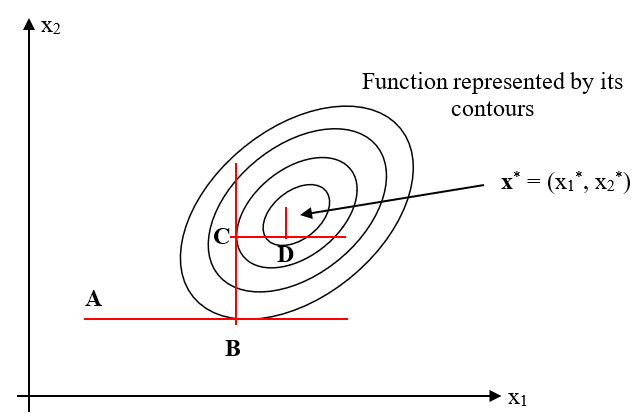

- The minimum of this function is located at (x1*, x2*). 

- The crudest and most obvious approach for obtaining the minimum is to iteratively minimise with respect to alternative variables.

- For example, referring to the diagram, we start at some point A and search in the direction of the x1-axis for the minimum in this direction, giving us point B.

- From B we then search in the direction of the x2-axis and obtain the minimum along this direction, i.e. point C.

- From C we search along the direction of the x1-axis once more and so on to the actual minimum point.

- Clearly, any of the line searches, in the previous section of the notes, could be used for each search.

- Also, this idea extends to functions of n variables.

- Before exploring different direct search algorithms in more detail, we need to examine and understand the basic mathematical notation that is used to represent line searches in n-dimensional space.

**Moving about in n-dimensional space**

- Consider a given n-vector **v**. This can be regarded as defining a point in n-space.

- Let **p** be another given n-vector. Now consider the n-vector **x** defined as follows:

                    $\mathbf{x}\left(\alpha \right)=\mathbf{v}+\alpha \mathbf{p}$, where $\alpha$ is a scalar.

- In other words, **x**(α) represents points on a straight line through **v** in the direction of **p** (positive or negative).

- Consider the example: $n=2,v={\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}\textrm{,}\;\;\mathrm{p}={\left[\begin{array}{c}
1\\
1
\end{array}\right]}\ldotp \;$Hence: ${\left[\begin{array}{c}
x_1 \\
x_2 
\end{array}\right]}={\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}+\alpha {\left[\begin{array}{c}
1\\
1
\end{array}\right]}$.

- Graphically, we can represent this as follows:

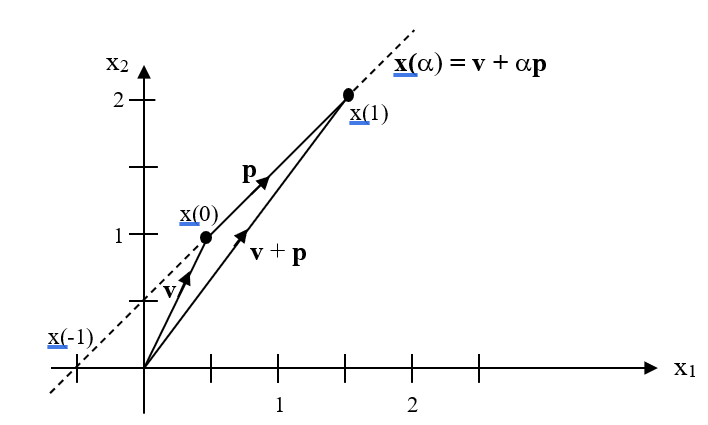

- The dashed line represents the line defined by the vector **x**. Hence, any point on a straight line passing through a point **v** in the direction **p** can be specified by a suitable choice of the variable α in the expression** x**(α) = **v** + α **p**.

- We can easily determine the familiar form of the equation of a straight line as follows. The above equations give:

                        $x_1$ = $½$ + $\alpha $ and   $x_2 = 1 + \alpha $

-   Substituting for α gives:                 $x_2 = x_1 + ½$                   $( y = mx + c )$

- Now we know how to represent a straight line in n-dimensional space. We can easily search along this line to obtain a minimum if we so wish

**Illustrative Example using line search and n-dimensional quadratic functions**

- Quadratic functions are the simplest form of n-dimensional functions which can have a local minimum. They take the general form:

                   
$$F(x) = a + b^Tx + ½ x^TG x$$


                  where a is a given scalar, **b** is a given n-vector and **G** is a given n x n ***symmetric*** matrix.

- Differentiation gives:

                   $\nabla F = b + Gx$      and   $\nabla^2 F = G$

- To ensure that the quadratic function has a unique minimum, we must choose G to be positive definite. 

- The actual position of the local minimum is given by $\nabla F = 0,$ i.e.:

                    $Gx^* = -b$,    which can be solved for $x^*$

- Note that although we can write $x^* = -G^{-1}b$, in practise, we tend to avoid computing $x^*$ by inverting **G**, as this is computationally intensive!

- For a 2-dimensional function (i.e. n = 2), we can represent F(**x**) graphically by means of a **contour plot**. For example, for a positive definite quadratic function, choose any value of F, say $k_1$, and plot all values of the vector **x** for which:

                   
$$b^Tx + ½ x^TG x = k_1$$


- The contours consist of a nest of ellipses centred on the local minimum $x^*$:

                                                       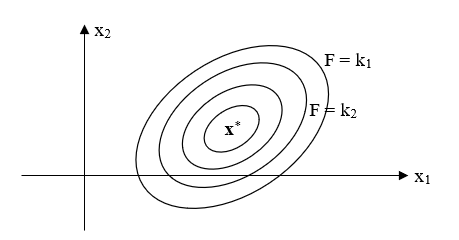

- Hence the position of $x^*$ is determined by the values of **b** and **G**. The orientation of the axes of the ellipses is determined by **G**.

- Now, let’s consider the 2-dimensional function:              F(**x**) = $x_1^2 +x_2^2$

- Hence:       F(**x**) = ${\left[\begin{array}{cc}
x_1  & x_2 
\end{array}\right]}\ {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}{\left[\begin{array}{c}
x_1 \\
x_2 
\end{array}\right]}=x^T \ I\ x$

- In other words, F(**x**) is a quadratic function where **G** = 2**I**.

- Contours are obtained by setting F to a series of constant values:

                            F(**x**) = 1 = $x_1^2 +x_2^2$     - unit circle

                            F(**x**) = 2 = $x_1^2 +x_2^2$     - circle, radius $\sqrt{2}$

                            etc...

- This gives the contour plot:

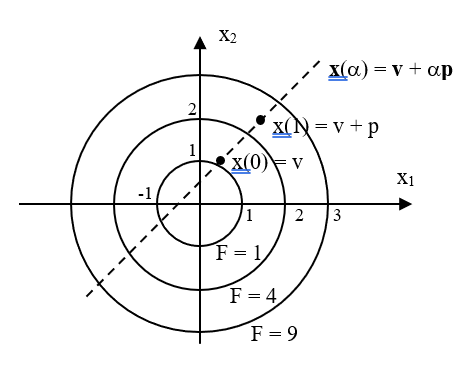

- **Matlab code part 01**

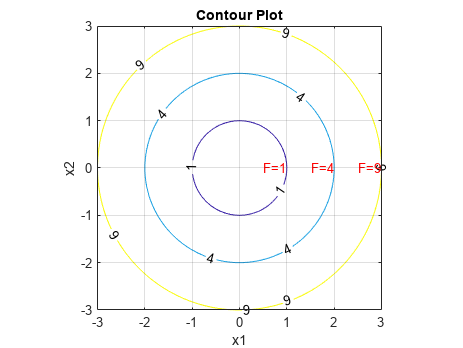

% Define the grid
[x1, x2] = meshgrid(-3:0.1:3, -3:0.1:3);

% Calculate the quadratic function F(x) = x1^2 + x2^2
F=x1.^2 + x2.^2;

% Generate the contour plot
contour(x1, x2, F, [1, 4, 9], 'ShowText', 'on'); % Show contours for F=1, F=4, and F=9
xlabel('x1');
ylabel('x2');
title('Contour Plot');

% Add annotations
hold on;
text(0.5, 0, 'F=1', 'FontSize', 10, 'Color', 'r');
text(1.5, 0, 'F=4', 'FontSize', 10, 'Color', 'r');
text(2.5, 0, 'F=9', 'FontSize', 10, 'Color', 'r');
hold off;

% Show the plot
grid on;
axis equal;

- Now consider the search line given in the previous example, i.e.:

                  Starting point $v={\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}$  and search direction $p={\left[\begin{array}{c}
1\\
1
\end{array}\right]}$.

- Hence, we have the search line, as shown by the dashed line above:


$${\left[\begin{array}{c}
x_1 \\
x_2 
\end{array}\right]}={\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}+\alpha {\left[\begin{array}{c}
1\\
1
\end{array}\right]}$$


- To obtain the equation of the section of F(**x**) cut by the straight line, we substitute **x**(α) into F(**x**):


$$F(\alpha ) = x^Tx  = (v + \alpha p)^T (v + \alpha p)$$



$$= v^Tv + 2\alpha p^Tv + \alpha^ 2p^Tp$$


- Evaluating gives:


$$v^Tv=$$

$${\left[\begin{array}{cc}
\textrm{0.5} & 1
\end{array}\right]}\ {\left[\begin{array}{c}
\textrm{0.5}\\
1
\end{array}\right]}=\textrm{0.25}+1=\textrm{1.25}$$


Similarly,  $p^Tv = 1.5,  p^Tp = 2$

- Hence:


$$F(\alpha ) = 1.25 + 3\alpha  + 2\alpha ^2$$


- Therefore the cross-section of F(x) along the link x(α) looks like:

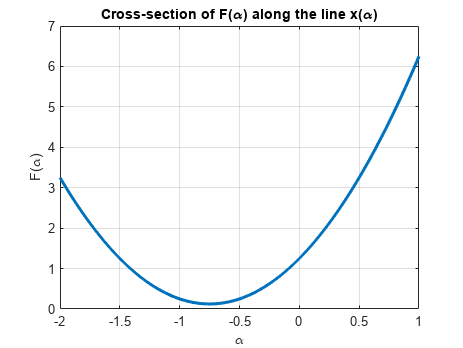

% Define the variables and given values
alpha = linspace(-2, 1, 1000); % Range of alpha
v = [0.5; 1];
p = [1; 1];

% Calculate F(alpha)
F_alpha = 1.25 + 3*alpha + 2*alpha.^2;


% Plot F(alpha)
figure;
plot(alpha, F_alpha, 'LineWidth', 2);
xlabel('\alpha');
ylabel('F(\alpha)');
title('Cross-section of F(\alpha) along the line x(\alpha)');
grid on;

- To find the minimum along this line, we could use one of our line searches if necessary, but in this case it’s simple to calculate the answer:


$$\frac{dF}{d\alpha}= 3 + 4\alpha  = 0 \rightarrow \alpha  = -0.75$$


$\frac{d^2 F}{\textrm{d}{\textrm{α}}^2 }$$=4>0 \rightarrow$ a minimum point

- Hence:

$x_{\min } ={\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}-\frac{3}{4}{\left[\begin{array}{c}
1\\
1
\end{array}\right]}$ $\rightarrow$ $x_1= -0.25$ and $x_2 = 0.25$


$$\rightarrow F(x_{min}) = 0.125$$


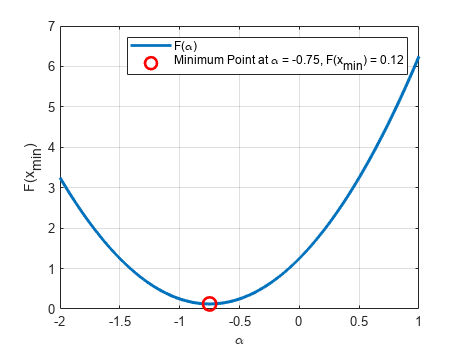

% Determine alpha_min by setting derivative to 0
syms a;
eqn = 3 + 4*a == 0;
alpha_min_calculated = double(solve(eqn, a));

% Calculate x_min
x_min = v + alpha_min_calculated * p;

% Evaluate F at x_min using the original F(x) formula
x1 = x_min(1);
x2 = x_min(2);
F_xmin = x1^2 + x2^2;

% Plot F(alpha) and the minimum point
figure;
plot(alpha, F_alpha, 'LineWidth', 2);
hold on;
plot(alpha_min_calculated, F_xmin, 'ro', 'MarkerSize', 10, 'LineWidth', 2); % minimum point
xlabel('\alpha');
ylabel('F(x_{min})');
%title('Cross-section of F(\alpha) along the line x(\alpha) and F(x_{min})');
legend('F(\alpha)', sprintf('Minimum Point at \\alpha = %.2f, F(x_{min}) = %.2f', alpha_min_calculated, F_xmin));
grid on;

- So now we can use this $x_{min}$ as our estimate of the local minimum (which is in fact equal to 0) or we can use it as a new starting point for the next search direction.

- Clearly, we can see how this direct search approach works.

- Such algorithms can be described in the following way:

-  Given an estimate $x^{(k)}$ of the position of a local minimum of F(**x**) at $x^*$, generate a search direction **p**(k) by some means.

- Find a minimum of the 1-dimensional function $F(x^{(k)}+ \alpha  p^{(k)})$. Let this minimum be at $\alpha ^{(k)}$.

- Set $x^{(k+1)} = x^{(k)} + \alpha ^{(k)}p^{(k)}$. Set $k = k+1$ and repeat.

- Here the value k represents the $k^{th}$ iteration.

- The question now becomes one of choosing the appropriate lines to search. In other words, for a given point, what is the best direction in which to search for a minimum?

#### **3.1 The Univariate Search Method**

- The univariate search adjusts the value of each function variable in turn. This corresponds to **using the co-ordinate axes as search directions**.

- In this case, the search direction vector is given by **e**i where the ithvalue contains a 1 to represent the axis of interest.

- Note that the vector $e_i$ is a unit vector in the direction of the $i^{th}$ axis. The size of the vector corresponds to the number of variables in the given function (and therefore the number of different axes!).

- For example, $e_1 = [1\quad 0\quad 0\quad \ldots]^T$ represents a unit vector in the direction of the $x_1$-axis.

- Hence, in the 2-D case, if we want to search in the direction of increasing (or decreasing) $x_1$, i.e. in a direction parallel to the $x_1$-axis, then the search direction **p** is given by:


$$p = e_1=$$
  
$${\left[\begin{array}{c}
1\\
0
\end{array}\right]}$$


- In general, **p** will be an $n$-dimensional vector and if we are searching in the direction of increasing (of decreasing) $x_i$ then the $i^{th}$ element will be 1, as follows:

$p = e_i=$${\left[\begin{array}{c}
0\\
\vdots \\
1\\
\vdots \\
0
\end{array}\right]}$.

**Illustrative Example** 

- Once again, consider the example:        $F(x) =$ $x_1^2 +x_2^2$ $= x^Tx$

- And consider the starting point: $x^{(0)} =$${\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}$ .

- Note that the superscript (0) represents the starting point (i.e. prior to the first iteration which will be denoted by superscript (1)).

- The graphical representation is as follows, where $x^{(0)}$ is the starting point and $p^{(1)}$ is the search direction of interest through this point:

 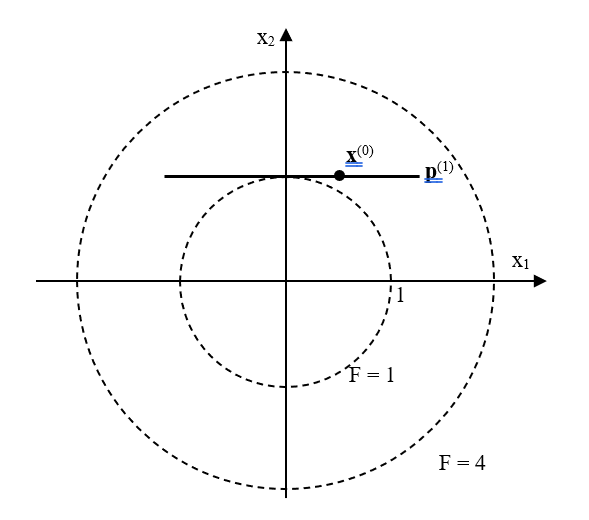

- The value of the function at this point is:


$$F(x^{(0)})$$
 
$$=$$
 
$${\left[\ \begin{array}{cc}
\frac{1}{2} & 1
\end{array}\right]}\ {\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}\ =\ 1\textrm{.25}$$


- Taking the first search direction in the direction parallel to the $x_1$-axis, we have:


$$p^{(1)} = e_1=$$

$${\left[\begin{array}{c}
1\\
0
\end{array}\right]}$$


- We want to obtain $x^{(1)}$, where $x^{(1)}$ $= x^{(0)} + \alpha p^{(1)}$. Hence, we need to find the value of α that minimises $F(\alpha )$:   *(note that *$x^{(1)}$ *is a function of the parameter *$\alpha $*, i.e. *$x^{(\alpha )}$*)*


$$F(\alpha )  = x(\alpha )^T x(\alpha )$$


                                   
$$= (x^{(0)} + \alpha  p^{(1)})^T (x^{(0)} + \alpha  p^{(1)})$$


                                                                                 
$$= (x^{(0)})^T x^{(0)} + 2\alpha  (p^{(1)})^T x^{(0)} + \alpha ^2(p^{(1)})^T p^{(1)}$$


- Evaluating each of these terms gives:


$$(x^{(0)})^T x^{(0)} = 1.25, \qquad       (p^{(1)})^T x^{(0)} = 0.5,  (p^{(1)})^Tp^{(1)} = 1$$


- Therefore: 


$$F(\alpha ) = 1.25 + \alpha  + \alpha ^2$$


- And:


$$\frac{\textrm{dF}}{\textrm{d}\textrm{α}}$$

$$= 1 + 2\alpha  = 0 \rightarrow \alpha  = -0.5$$


$\frac{d^2 F}{\textrm{d}{\textrm{α}}^2 }$$= 2 > 0 \rightarrow$ Minimum at $\alpha  = -0.5$

- Now: $x^{(1)} = x^{(0)}+ \alpha p^{(1)}$ = ${\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}+{\left(-\frac{1}{2}\right)}{\left[\begin{array}{c}
1\\
0
\end{array}\right]}$ $\rightarrow$${\left[\begin{array}{c}
0\\
1
\end{array}\right]}$

- Also: $F(x^{(1)}) =$${\left[\begin{array}{cc}
0 & 1
\end{array}\right]}\ {\left[\begin{array}{c}
0\\
1
\end{array}\right]}\ =\;\textrm{1}$

- These results are illustrated below:

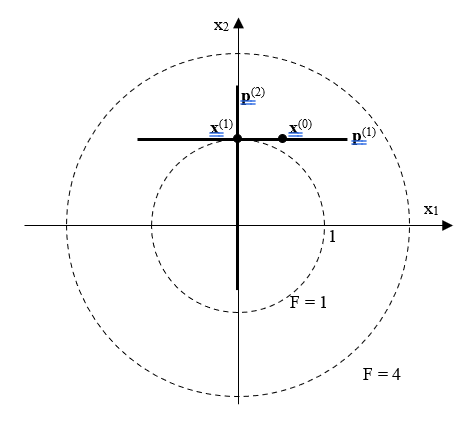

- Now take the next search direction, parallel to the $x_2$-axis, i.e.: $p^{(2)} =$${\left[\begin{array}{c}
0\\
1
\end{array}\right]}$

- From the diagram, we can see that this iteration should bring us straight to the actual minimum … let’s see! 

- We now want to obtain $x^{(2)}$, where $x^{(2)} = x^{(1)} + \alpha p^{(2)}$. Again, we need to find the value of $\alpha $ that minimises $F(\alpha )$.

- Evaluating $F(\alpha )$ with the new updates:

$(x^{(1)})^T x^{(1)} = 1,$             $(p^{(2)})^T x^{(1)}= 1$,              $(p^{(2)})^T p^{(2)}= 1$


$$\therefore F(\alpha ) = 1 + 2\alpha  + \alpha ^2$$


$\frac{\textrm{dF}}{\textrm{d}\textrm{α}}$= $2 + 2\alpha  = 0 \rightarrow \alpha  = -1$

$\frac{d^2 F}{\textrm{d}{\textrm{α}}^2 }$ $= 2 > 0 \rightarrow$ Minimum at $\alpha  = -1$

- Now: $x^{(2)} = x^{(1)}+ \alpha p^{(2)}$ $=$ ${\left[\begin{array}{c}
0\\
1
\end{array}\right]}+{\left(-1\right)}{\left[\begin{array}{c}
0\\
1
\end{array}\right]}$ $\rightarrow$${\left[\begin{array}{c}
0\\
0
\end{array}\right]}$

- 
$$F(x^{(2)}) =$$

$${\left[\begin{array}{cc}
0 & 0
\end{array}\right]}\ {\left[\begin{array}{c}
0\\
0
\end{array}\right]}\ =\;\textrm{0}$$


- This must be a minimum since $F(x) \geq 0$

- Check:


$$\frac{\partial F}{\partial x_1 }=\textrm{2}{\textrm{x}}_1 =\textrm{0}\;\;\textrm{at}\;\;{\textrm{x}}^{\left(2\right)}$$
               
$$\frac{\partial^2 F}{\partial x_1^2 }=2$$



$$\frac{\partial F}{\partial x_2 }=\textrm{2}{\textrm{x}}_2 =\textrm{0}\;\;\textrm{at}\;\;{\textrm{x}}^{\left(2\right)}$$
                
$$\frac{\partial^2 F}{\partial x_2^2 }=2$$
 


$$\frac{\partial^2 F}{\partial x_1 \partial x_2 }=0=\frac{\partial^2 F}{\partial x_2 \partial x_1 }$$


- This gives the matrix ${\left[\begin{array}{cc}
2 & 0\\
0 & 2
\end{array}\right]}$, which is positive definite.

- Using the facts that the slope of F(**x**) along any direction $p$ is $p^T$$\nabla F$ and that $\nabla F$ is orthogonal to the contour at every point, we can predict the sequence of points obtained.

- Although we only required 2 iterations in the last example, in general, the univariate search method requires many iterations and, therefore, many evaluations of $F$.

- For example, consider the following diagram, where the contours do not line up so conveniently with the $x_1$ and $x_2$ axes (as in the last example). In this case, it will take several iterations before we converge to the minimum point.

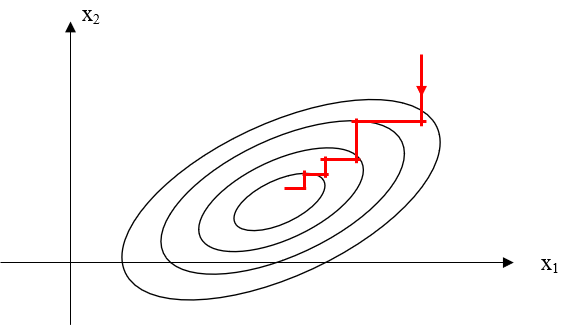

- The problem with univariate search is that it doesn’t learn – it always uses the same set of search iterations.  The Davies Swann and Campey Algorithm attempts to alleviate this problem.

#### **3.2 The Davies Swann and Campey Algorithm (DSC)** 

- This begins by carrying out n iterations of univariate search. The search direction on iteration (n + 1) is taken as the direction from $x^{(0)}$ to $x^{(n)}$, i.e.: $x^{(n)} - x^{(0)}$

- Let **one cycle of the DSC algorithm** be defined as a set of n successive iterations of univariate search.

- Let $p_j^{(k)}$ be the $j^{th}$ direction of search on the $k^{th}$ cycle.

- Let $x_j^{(k)}$ be the $j^{th}$ point generated on the $k^{th}$ cycle.

- Then, **on cycle 1** (i.e. the first n iterations of the univariate search), we have $n$ search directions:

  
$$p_1^{(1)} = e_1$$


 :        :


$$p_i^{(1)} = e_i$$


         :        :        

  
$$p_n^{(1)} = e_n$$


where $e_1 =$ ${{\left[\begin{array}{ccccc}
1 & 0 & 0 & \cdots  & 0
\end{array}\right]}}^T$ , $e_i=$ ${{\left[\begin{array}{ccccc}
0 & \cdots  & 1 & \cdots  & 0
\end{array}\right]}}^T$ , etc…

- The corresponding set of points generated is:      $x_1^{(1)}, \ldots, x_i^{(1)}, \ldots, x_n^{(1)}$

- Starting from $x_0^{(1)}$ (arbitrary starting value), we use the formula:

                  
$$x_i^{(1)} = x_{i-1}^{(1)}+ \alpha _i^{(1)} p_i^{(1)}$$


- Recall that $\alpha _i^{(1)}$ is chosen to minimise $F$ along the search direction $p_i^{(1)}$

- On the next cycle (i.e. the second cycle) we start by choosing:


$${p_1 }^{\left(2\right)} =\frac{{x_n }^{\left(1\right)} -{x_0 }^{\left(1\right)} }{\left|\right|{x_n }^{\left(1\right)} -{x_0 }^{\left(1\right)} \left|\right|}$$


- Note that the denominator simply scales the vector to ensure a vector of unit length. The direction of the search line remains unchanged.

- This leaves us with n-1 directions to find! We then need to generate n-1 directions orthogonal to $p_1^{(2)}$ and to each other.

- The method normally used to do this is the **Gram-Schmidt Orthogonalisation method**.

- Before we look at this method, let’s illustrate how the DSC algorithm works graphically - we will consider the case of $n = 2$.

-  Hence, we have two search directions to consider for each cycle. The first cycle is just the same as carrying out the standard univariate search method:

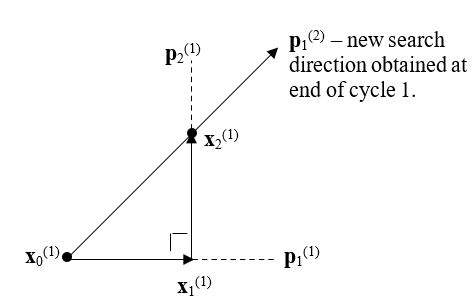

- At the end of the first cycle the new search direction $p_1^{(2)}$ is the line joining $x_0^{(1)}$ and $x_2^{(1)}$ as shown above. 

- This is the fundamental difference between the DSC algorithm and the basic univariate search method.

- We now obtain the minimum along the new search direction and, from this point, generate a new search direction orthogonal (i.e. perpendicular) to the current one.

- Note that the end point of cycle 1 is the start point of cycle 2, i.e.:        

                  
$$x_2^{(1)} = x_0^{(2)}$$
 

- The first and second cycles of the DSC algorithm are shown below:

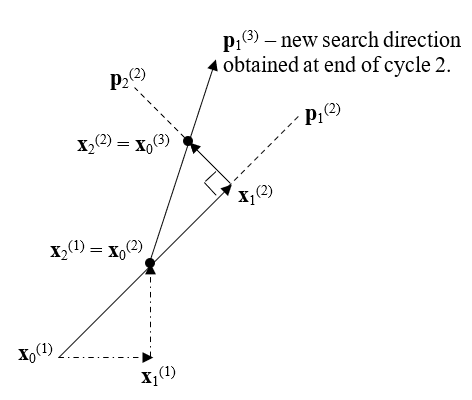

- At the end of the second cycle, we now have the new search direction $p_1^{(3)}$. And thus, the process continues until we obtain a suitable minimum value – for example, if the difference between two successive estimates of the minimum is sufficiently small.

- Note that the search direction $p_2^{(2)}$ is orthogonal to $p_1^{(2)}$. How do we obtain this search direction?

- As mentioned earlier, the method normally used to do this is the **Gram-Schmidt Orthogonalisation method**.

#### **Gram-Schmidt Orthogonalisation Method**

- We begin by defining a matrix $P^{(k)}$, where $k$ represents the current DSC cycle, as:


$$[ p_1^{(k)} \quad  p_2^{(k-1)} \quad  \cdots \quad   p_n^{(k-1)} ]$$


- We know the current search direction $p_1^{(k)}$. The other search directions are from the previous cycle, but this is fine. All we need are vectors that belong to the plane associated with each of the different function variables. 

- It is important that the first column is the current search direction, because, as we will soon see, this is also the first column vector of the **Q** matrix, which will store our desired orthogonal search directions.

- We are looking for matrices **Q** and **U** such that: 

                           $Q^TQ = I$,   the unit identity matrix (nxn) and

                           $QU = P^{(k)}$,  where **U** is an upper triangular matrix (i.e. the bottom half off-diagonal terms                            are all zero)

- Let $Q$ be written as $[q_1 \quad   q_2  \cdots \quad q_n]$, where $q_i$ is the $i^{th}$ column vector. Since $Q^TQ = I$, all the column vectors of $Q$ are orthogonal to each other. This is what we are looking for! 

- The matrix **U** is given by:

  
$${\left[\begin{array}{cccc}
u_{\textrm{11}}  & u_{\textrm{12}}  & \cdots  & u_{\textrm{1n}} \\
0 & u_{\textrm{22}}  & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & \vdots \\
0 & \cdots  & 0 & u_{\textrm{nn}} 
\end{array}\right]}$$


- Then $QU = P^{(k)}$ gives:


$$[q_1 \quad   q_2  \cdots \quad q_n]$$

$${\left[\begin{array}{cccc}
u_{\textrm{11}}  & u_{\textrm{12}}  & \cdots  & u_{\textrm{1n}} \\
0 & u_{\textrm{22}}  & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & \vdots \\
0 & \cdots  & 0 & u_{\textrm{nn}} 
\end{array}\right]}$$
 
$$= [ p_1^{(k)} \quad   p_2^{(k-1)}  \cdots \quad  p_n^{(k-1)} ]$$


- Multiply out the LHS and equate columns of matrices on LHS side to those on the RHS. 

- For the first column we obtain: 

                  $u_{11} q_1 = p_1^{(k)}$                    (equation X for reference purposes)

- Pre-multiplying both sides by its own transpose gives:

                  
$$(u_{11}q_1)^T(u_{11}q_1) = (p_1^{(k)})^T(p_1^{(k)})$$


- ***Note 1 :*** The vector $p_1^{(k)}$ is normalised to have a unit length. Hence $(p_1^{(k)})^T(p_1^{(k)}) = 1$.

- For example, take the vector $k = [k_1\quad k_2]^T$. The normalised vector is given by:


$${{\left[\begin{array}{cc}
\frac{k_1 }{\sqrt{k_1^2 +k_2^2 }} & \frac{k_2 }{\sqrt{k_1^2 +k_2^2 }}
\end{array}\right]}}^T$$


- And therefore:

$k^Tk =$$\ {\left[\begin{array}{cc}
\frac{k_1 }{\sqrt{k_1^2 +k_2^2 }} & \frac{k_2 }{\sqrt{k_1^2 +k_2^2 }}
\end{array}\right]}{\left[\begin{array}{c}
\frac{k_1 }{\sqrt{k_1^2 +k_2^2 }}\\
\frac{k_2 }{\sqrt{k_1^2 +k_2^2 }}
\end{array}\right]}$= $\frac{k_1^2 }{{{\left(\sqrt{k_1^2 +k_2^2 }\right)}}^2 }+\frac{k_2^2 }{{{\left(\sqrt{k_1^2 +k_2^2 }\right)}}^2 }=1$

- ***Note 2:*** We know that $Q^TQ = I$, i.e.:


$${\left[\begin{array}{cccc}
{\mathit{\mathbf{q}}}_1  & {\mathit{\mathbf{q}}}_2  & \cdots  & {\mathit{\mathbf{q}}}_{\mathit{\mathbf{n}}} 
\end{array}\right]}\mathit{\mathbf{\ }}{\left[\begin{array}{c}
{\mathit{\mathbf{q}}}_1 \\
{\mathit{\mathbf{q}}}_2 \\
\vdots \\
{\mathit{\mathbf{q}}}_{\mathit{\mathbf{n}}} 
\end{array}\right]}\mathit{\mathbf{\ }}=\mathit{\mathbf{\ }}{\left[\begin{array}{cccc}
1 & 0 & \cdots  & 0\\
0 & 1 & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots \\
0 & 0 & \cdots  & 1
\end{array}\right]}$$


- Multiplying out gives $q_1^Tq_1 = 1$, etc… 

- Also note that off diagonal terms are zero, i.e. $q_1^Tq_2 = 0$, etc…

- Evaluating gives:

                  
$$u_{11}^2 q_1^Tq_1 = (p_1^{(k)})^T(p_1^{(k)})$$


                  
$$\rightarrow u_{11}^2(1) = 1$$


- Therefore, since $u_{11}= 1$, equation X now gives:      $q_1= p_1^{(k)}$

- Hence the first column of the matrix $Q$ is the same as the first one of matrix $P$.

- Now consider the second column of the expansion of $QU = P^{(k)}$:                                                                                   

                  $u_{12} q_1 + u_{22} q_2 = p_2^{(k-1)}$                  (equation Y for reference purposes)

- Pre-multiplying both sides by $q_1^T$ gives:

                  
$$u_{12}q_1^T q_1 + u_{22} q_1^T q_2 = q_1^T p_2^{(k-1)}$$


                  
$$\rightarrow u_{12} (1) + u_{22} (0) = q_1^T p_2^{(k-1)}$$


                  
$$\rightarrow u_{12}= q_1^T p_2^{(k-1)}$$


- Since we know both $q_1^T$ and $p_2^{(k-1)}$ we can calculate $u_{12}$.

- Rearranging equation Y gives:

                  
$$u_{22} q_2 = p_2^{(k-1)} - u_{12} q_1$$


- Squaring both sides gives:

                  $u_{22}^2 q_2^T q_2 = || p_2^{(k-1)} - u_{12} q_1||^2$       ( … note that for a vector $a, a^Ta = ||a||^2$)  

                  
$$\rightarrow u_{22}^2(1) = || p_2^{(k-1)}- u_{12} q_1||^2$$


                  
$$\rightarrow u_{22} = || p_2^{(k-1)} - u_{12}q_1||$$


- All the values on the RHS side are known and therefore $u_{22}$ can be calculated.

- Hence, we can determine $q_2$ as follows:


$$q_2 =$$

$$\frac{{p_2 }^{\left(k-1\right)} -u_{\textrm{12}} q_1 }{{\left‖\ {p_2 }^{\left(k-1\right)} -u_{\textrm{12}} q_1 \right‖}}$$


- Continuing in this way for the other columns, we obtain in general for the ith column:

                  
$$u_{ji} = q_j^T p_i^{(k-1)},     \quad         j = 1, 2, \ldots., i-1$$


and   $q_i=$ $\frac{{p_i }^{\left(k-1\right)} -\sum_{j=1}^{\textrm{i-1}} u_{\textrm{ji}} q_j }{{\left‖\ {p_i }^{\left(k-1\right)} -\sum_{j=1}^{\textrm{i-1}} u_{\textrm{ji}} q_j \right‖}}$ 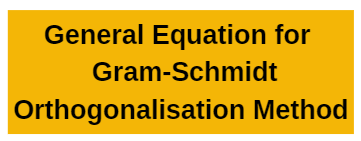

- The search directions are then $q_1, q_2, \ldots, q_n$.

- The reason for using orthogonal search directions is so that we don’t end up searching along the same plane all the time! 

- Note – in practice, the DSC algorithm is modified so that a new set of directions are only used on iteration k if a reasonably large step has been taken on the previous iteration, k-1. 

**Illustrative Example of DSC algorithm and Gram-Schmidt Orthogonalisation**

-  Consider the following function (with n = 2):

                  
$$f(x) = x_1x_2 + x_1^2 + 2x_2^2$$


- Taking the initial starting point $x_0= [1\quad 1]^T$, carry out two complete cycles of the Davies, Swann and Campey algorithm.

- The first cycle is the same as the univariate method!

- Calculating the function at $x_0$ gives  $f(x_0) = 4$.

- Taking the first search direction in the direction parallel to the x1-axis, we have:

                  
$$p_1^{(1)} = e_1=$$
 
$${\left[\begin{array}{c}
1\\
0
\end{array}\right]}$$


- Hence:  $x_1^{(1)}= x_0^{(0)} + \alpha  p_1^{(1)}$

- This gives:              $x_1^{(1)} =$${\left[\begin{array}{c}
1\\
1
\end{array}\right]}+\alpha {\left[\begin{array}{c}
1\\
0
\end{array}\right]}={\left[\begin{array}{c}
\alpha +1\\
1
\end{array}\right]}$ 

- Need to find $\alpha $, by minimising $f(\alpha )$:


$$f(\alpha ) = (\alpha  + 1)\times1 + (\alpha  + 1)^2+ 2\times(1)^2 = \alpha ^2 + 3\alpha  + 4$$


$\frac{\textrm{df}}{\textrm{d}\textrm{α}}$$= 2\alpha  + 3 = 0$       $\rightarrow \alpha  = -1.5$ and    $f(\alpha ) = 1.75$

$\frac{d^2 f}{\textrm{d}{\textrm{α}}^2 }$$= 2 > 0$     $\rightarrow$ minimum

- Hence:  $x_1^{(1)}=$${\left[\begin{array}{c}
-0.5\\
1
\end{array}\right]}$

- Our next search direction is:

                  
$$p_2^{(1)} = e_2=$$
 
$${\left[\begin{array}{c}
0\\
1
\end{array}\right]}$$


- Therefore: $x_2^{(1)} =$ ${\left[\begin{array}{c}
\textrm{-0.5}\\
1
\end{array}\right]}+\alpha {\left[\begin{array}{c}
0\\
1
\end{array}\right]}={\left[\begin{array}{c}
\textrm{-0.5}\\
\alpha +1
\end{array}\right]}$

- Once again, we find $\alpha $, by minimising $f(\alpha )$. 

- This gives $\alpha  = -0.875$ (minimum) and $f(\alpha ) = 0.21875$. Verify these values for yourself!

- This completes the first cycle. At the start of the second cycle we know that:


$$x_0^{(2)} = x_2^{(1)}=$$
 
$${\left[\begin{array}{c}
\textrm{-0.5}\\
\textrm{0.125}
\end{array}\right]}$$


- The new search direction, according to DSC, is given by:


$${p_1 }^{\left(2\right)} =\frac{{x_2 }^{\left(1\right)} -{x_0 }^{\left(1\right)} }{\left|\right|{x_2 }^{\left(1\right)} -{x_0 }^{\left(1\right)} \left|\right|}$$


- ***Note: the scaling factor is only important for the Gram-Schmidt orthogonalisation part. It makes absolutely no difference to the direction itself. Therefore, for now, it’s sufficient to take:***


$${p_1 }^{\left(2\right)} ={x_2 }^{\left(1\right)} -{x_0 }^{\left(1\right)}$$


- Calculating this gives:


$$p_1^{(2)} =$$
 
$${\left[\begin{array}{c}
\textrm{-1.5}\\
\textrm{-0.875}
\end{array}\right]}$$


- Now we determine the next point as:

                  
$$x_1^{(2)}= x_0^{(2)} + \alpha  p_1^{(2)}$$


- This gives: $x_1^{(2)} =$${\left[\begin{array}{c}
\textrm{-0.5}\\
\textrm{0.125}
\end{array}\right]}+\alpha {\left[\begin{array}{c}
\textrm{-1.5}\\
\textrm{-0.875}
\end{array}\right]}={\left[\begin{array}{c}
\textrm{-0.5-1.5}\textrm{α}\\
\textrm{0.125-0.875}\textrm{α}
\end{array}\right]}$ 

- Once again, find $\alpha$ by minimising $f(\alpha)$`:`

    
$$f(\alpha) = 5.09375\alpha^2 + 1.3125\alpha + 0.21875$$


    $\frac{df}{d\alpha} = 10.1875\alpha + 1.3125 = 0$ $\rightarrow \alpha = -0.1288$` and `$f(\alpha) = 0.1342$

    $\frac{d^2f}{d\alpha^2} = 10.1875 > 0$ $\rightarrow$ minimum

- Hence:       $x_1^{(2)}=$${\left[\begin{array}{c}
-0.3068\\
0.2377
\end{array}\right]}$

- At this stage, we need to generate a search direction orthogonal to$p_2^{(2)}$`.`

- The Gram-Schmidt orthogonalisation method gives:


$$u_{12} = q_1^T p_2^{(k-1)}$$


- and 


$$q_2 = \frac{p^{(k-1)} - u_{12} q_1}{\| p^{(k-1)} - u_{12} q_1 \|}$$


- Here, $q_1$ is the normalised version of $p_1^{(2)}$, i.e.:


$$q_1=$$

$$\frac{{p_1 }^{\left(2\right)} }{\left|\right|{p_1 }^{\left(2\right)} \left|\right|}=\frac{{\left[\begin{array}{c}
\textrm{-1.5}\\
\textrm{-0.875}
\end{array}\right]}}{\sqrt{\left(\textrm{-1.5}{\left.\right)}^2 +\left(-0.875{\left.\right)}^2 \right.\right.}}={\left[\begin{array}{c}
\textrm{-0.8638}\\
\textrm{-0.5039}
\end{array}\right]}$$


- Recall that k represents the cycle number, therefore $p_2^{(k-1)} = p_2^{(1)}$ which is:


$$p_2^{(1)} =$$

$${\left[\begin{array}{c}
0\\
1
\end{array}\right]}$$


- Hence, we calculate $u_{12}$ as follows:


$$u_{12}=$$

$${\left[\begin{array}{cc}
-\textrm{0.8638} & -\textrm{0.5039}
\end{array}\right]}\ {\left[\begin{array}{c}
0\\
1
\end{array}\right]}=-\textrm{0.5039}$$


- And $q_2$, the orthogonal vector, is determined as follows:

                   
$$q_2 =$$

$${\left[\begin{array}{c}
0\\
1
\end{array}\right]}+0.5039{\left[\begin{array}{c}
-0.8638\\
-0.5039
\end{array}\right]}={\left[\begin{array}{c}
-0.4353\\
0.7461
\end{array}\right]}$$


- Once again, for convenience, we have not normalised this vector as, for now, we are only using it as a search direction.

- Our new search direction $p_2^{(2)}$ is given by the vector $q_2$.

- Now we determine the next point as:


$$x_2^{(2)} = x_1^{(2)}+ \alpha  p_2^{(2)}$$


- This gives:


$$x_2^{(2)} =$$

$${\left[\begin{array}{c}
\textrm{-0.3068}\\
\textrm{0.2377}
\end{array}\right]}+\alpha {\left[\begin{array}{c}
\textrm{-0.4353}\\
\textrm{0.7461}
\end{array}\right]}={\left[\begin{array}{c}
\textrm{-0.3068-0.4353}\textrm{α}\\
\textrm{0.2377}+\textrm{0.7461}\textrm{α}
\end{array}\right]}$$


- Once again, find $\alpha $ by minimising $f(\alpha )$:


$$f(\alpha) = 0.978\alpha^2 + 0.6441\alpha + 0.1342$$


$\frac{df}{d\alpha} = 1.956\alpha + 0.6441 = 0$  $\rightarrow \alpha = -0.3293$ and $f(\alpha) = 0.02815$

$\frac{d^2f}{d\alpha^2} = 1.956 > 0$  $\rightarrow$ minimum

- Hence:       $x_0^{(3)}= x_2^{(2)} =$${\left[\begin{array}{c}
-0.1635\\
-0.008
\end{array}\right]}$

- This is the end of the second cycle. 

- The actual minimum is $x = [0\quad 0]^T$, so we are clearly getting close!

- In general, how do we know when to terminate an algorithm, especially if we don’t know the minimum?

- There are two criteria that can be used. For our example:

(i) if $||x^{(2)} - x^{(0)}|| < \varepsilon_1$ or

(ii) if $|f(x^{(2)}) - f(x^{(0)})| < \varepsilon_2$

- Here $\varepsilon_1$ and $\varepsilon_2$ are pre-defined small positive values.

- In our case we obtain:

(i) $|| x_2^{(2)} – x_0^{(2)}||$ =${\left‖\ {\left[\begin{array}{c}
\textrm{0.3365}\\
-\textrm{0.133}
\end{array}\right]}\ \right‖}$= 0.3618

or

(ii) $| f (x_2^{(2)}) – f(x_0^{(2)})| = | 0.02815 - 0.21875 | = 0.1906$

- Therefore, if $0.3618 <$ $\varepsilon_1$ then we can stop searching.

- Alternatively, if $0.1906 <$ $\varepsilon_2$, then we can stop the algorithm.

- Either one or both conditions can be use, with the appropriate tolerance value(s) specified at the start of the algorithm. 

- In this example, we were only asked to carry out two iterations, so we don’t need to worry about termination!

- The following contour map shows a graphically representation of what has happened thus far:

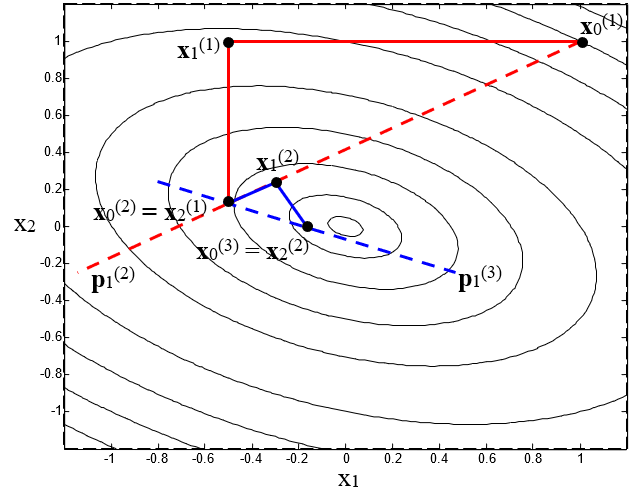

- Continuing for a few more iterations, we will eventually converge on the minimum as shown below:

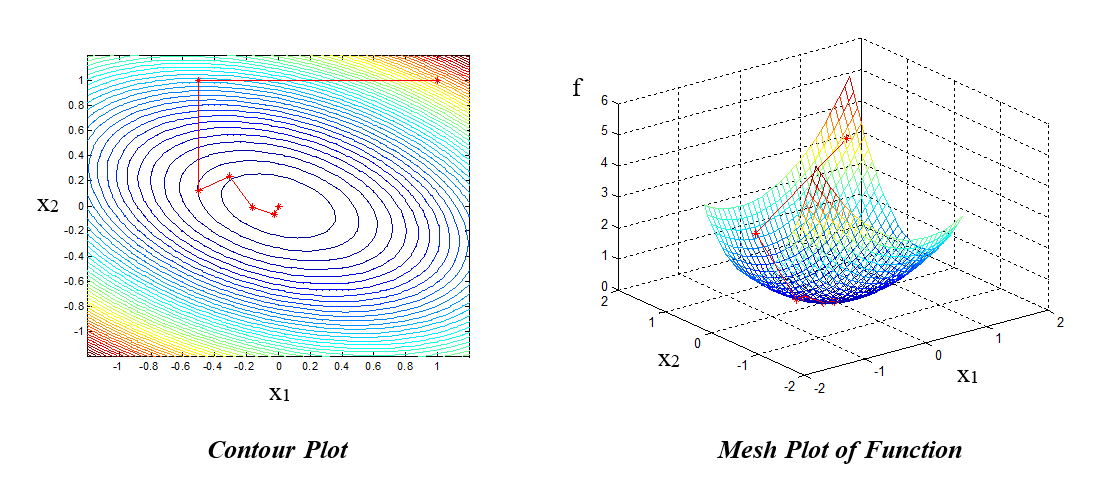

**Matlab code**

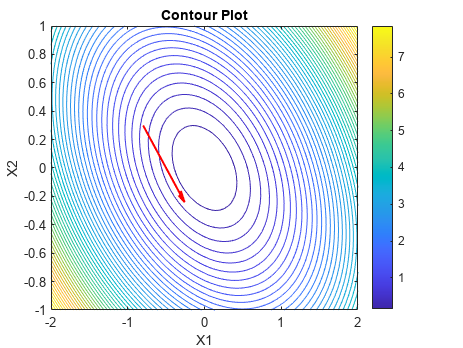

% Define the variables
[X1, X2] = meshgrid(-2:0.05:2, -1:0.05:1); % Define a grid of x1 and x2 values

% Calculate the function f(x) = x1*x2 + x1^2 + 2*x2^2
F = X1.*X2 + X1.^2 + 2*X2.^2;

% Contour Plot
figure;
contour(X1, X2, F, 50); % Create a contour plot with 50 contour levels
colorbar;
title('Contour Plot');
xlabel('X1');
ylabel('X2');
hold on;
% Adding the trajectory (assuming it's a simple arrow as illustrated)
quiver(-0.8, 0.3, 0.6, -0.6, 'r', 'LineWidth', 1.5, 'MaxHeadSize', 0.5); 
hold off;

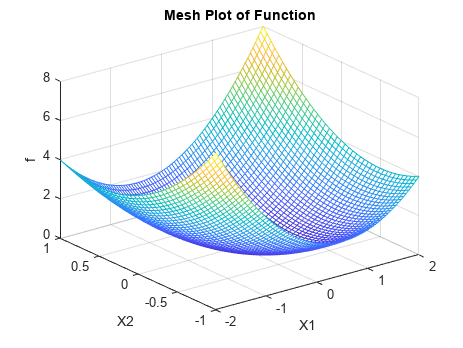


% Mesh Plot of Function
figure
mesh(X1, X2, F); % Create a mesh plot
title('Mesh Plot of Function');
xlabel('X1');
ylabel('X2');
zlabel('f');

**3.3 The Simplex Method (Nelder and Mead)**

- The Simplex method is another direct search method but takes a very different approach to the Univariate and the DSC search methods when it comes to determining the sequence of one-dimensional search directions.

- The original Simplex method was derived by Spendley, Hext and Himsworth but was later improved upon by Nelder and Mead.

- First off, a **simplex** in n-dimensional space is a polygon with n+1 vertices. 

- In 2-D space, the simplex is a triangle. In other words,  the three points must not lie on a straight line. Similarly, in 3-D space, the 4 points must not lie on the same plane, etc.

- The Simplex method evaluates the function at each of the vertices in the simplex.

- A new point is then generated, and the function is evaluated at this point. The point with the largest function value is rejected and the new point is subsequently introduced into the simplex. 

- In this fashion, a sequence of new simplices is created, with the best point in the simplex converging to a local minimum.

- The generation of the new point is obtained by the application of three basic operations – namely ***reflection***, ***expansion***and ***contraction***.

- The Simplex algorithm is now outlined using a 2-D example. In other words we will use a triangle (with n = 2) to illustrate the operation of the Simplex method.

-  Consider the 3 points, $x_{low}$, $x_m$, $x_h$ of a simplex in 2-D space as shown below. The choice of this initial simple is entirely arbitrary.

 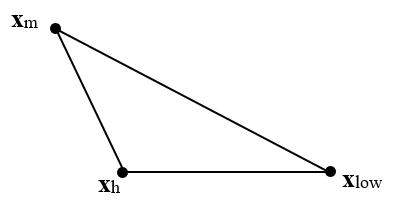

- **Step 1 **- We calculate the function at each of these points and rank them from the lowest to the highest. Let's say that:


$$F(x_{low}) \leq F(x_m) \leq F(x_h)$$


- Find the centroid, say $x_g$, of all the points, except $x_h$ (i.e. the one giving the highest function value):


$$x_g = \frac{1}{n} \sum_{i \neq h} x_i$$


- **Step 2** - Reflection - A new point is generated by reflecting $x_h$ about the centroid, as illustrated below:

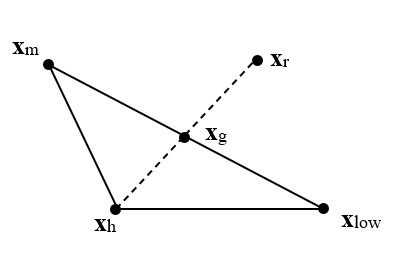

- The reflected point $x_r$ satisfies the condition:


$$x_h - x_g = x_g - x_r$$


or


$$x_r = 2x_g - x_h$$


- If $F(x_r) \geq F(x_m)$ then it's possible that we have moved too far out of the simplex and a better point may be found by making a contraction – go to step 3.

- If, instead, $F(x_m) > F(x_r) > F(x_i)$ then we have found an improvement on $x_m$. We therefore replace the worst point $x_h$ with $x_r$ and return to step 1.

- If, finally, $F(x_r) < F(x_{low})$ then we have found the best point to date. At this stage we make the reasonable assumption that a larger step beyond $x_r$ may lead to an even better point.

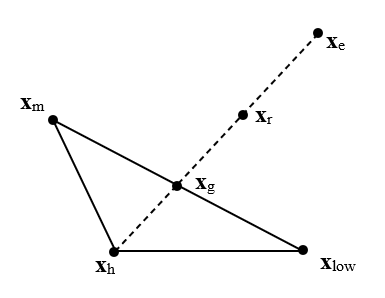

- The expanded point, $x_e$, is obtained such that: 

$x_e - x_g = \mu (x_r - x_g)$,         with $\mu > 1$. 

or  $x_e = x_g (1 - \mu) + \mu x_r$.

- Now, if $F(x_e) < F(x_r)$, then replace the worst point $x_h$ with $x_e$ and return to step 1. 

- Otherwise, $x_r$ is the better point and therefore replace $x_h$ with $x_r$ and return to step 1.

- **Step 3 - Contraction – **There are two possible scenarios:

- ***Scenario 1:*** If it turns out that $F(x_r) \geq F(x_h)$$ then we look for a point $x_c$, located on the line joining $x_h$ and $x_g$, that is better than the point $x_r$.

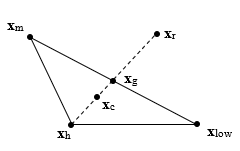

- We make a contraction of the original simplex with the condition: 

$x_c - x_g = \eta(x_h - x_g)$, with $0 < \eta < 1$

 or 


$$x_c = x_g(1 - \eta) + \eta x_h$$


- Now, if $F(x_c) < F(x_h)$ we replace $x_h$ with $x_c$ and go to step 1. Otherwise we go to step 4.

         2. **Scenario 2: ** If $F(x_r) < F(x_h)$, we look for a point $x_c$, located on the line joining $x_g$ and $x_r$:

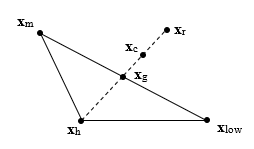

- The point $x_c$ now satisfies the condition: 

$x_c - x_g = \eta(x_r - x_g)$, with $0 < \eta < 1$ 

or


$$x_c = x_g(1 - \eta) + \eta x_r$$$


- Now, if $F(x_c) < F(x_r)$ we replace $x_h$ with $x_c$ and go to step 1, otherwise go to step 4. (Note, finding $F(x_c) < F(x_h)$ is pointless considering that we know that $F(x_r) < F(x_h)$ at this stage!)

- **Step 4 - Reduction of Simplex** – To reach this step, reflection, expansion and contraction have all failed to return a point better than $x_h$

- Therefore, it appears that the minimum is enclosed by the current simplex.

- We now contract the simplex around the best point by reducing each side by half.

- In order words, each point in the simplex, **x**iis replaced by:    $\frac{x_i +x_{\textrm{low}} }{2}$

- Graphically:

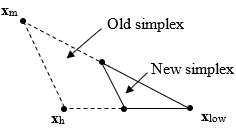

- We then proceed to step 1 and repeat the process. 

- Note the expansion factor is typically taken as $\mu = 2$, while the contraction factor is typically $\eta = \frac{1}{2}$.

**Convergence**

- For each new simplex, we should test for convergence before continuing. One possible criterion is that the simplex satisfies: $\sum_{i=1}^{n+1} |F(x_i) - F(x_{\text{low}})| < \varepsilon$

- where $\varepsilon$ is a positive small value.

- This criterion establishes a simplex having a deviation from the best obtained value less than $\varepsilon$.

- If this criterion is met, then $x_{\text{low}}$ is taken to be the estimate of the minimum and the simplex algorithm is terminated.

**Illustrative Example of Simplex algorithm**

- Once again, let us consider the following function (with n = 2):

                   
$$f(x) = x_1x_2 + x_1^2+ 2x_2^2$$
 

- Taking the initial starting points $x_0 = [1\quad 1]^T, x_1 = [-0.5\quad 1]^T$ and $x_2 = [-0.5\quad 0]^T$, carry out two iterations of the Simplex algorithm. Sketch the simplex after each iteration.

- **First iteration**  - The first step is to determine the order of the points in terms of their function output:

                   
$$f(x_0) = 4,   f(x_1) = 1.75,   f(x_2) = 0.25$$


- Hence $x_0$ is the worst point and $x_2$ is the best point. For convenience, we’ll denote:

                   $x_h = x_0 =$${\left[\begin{array}{c}
1\\
1
\end{array}\right]}$ ,  $x_m= x_1 =$ ${\left[\begin{array}{c}
-0.5\\
1
\end{array}\right]}$    and   $x_{low} = x_2 =$ ${\left[\begin{array}{c}
-0.5\\
0
\end{array}\right]}$

                  where $x_h, x_m$ and $x_{low}$ represent the high (or worse), middle and low (or best) points respectively. 

- We now determine the centroid **x**g using the best two (or n) points: 

                   $x_g = 0.5 (x_{low} + x_m)$$= 0.5$${\left[\begin{array}{c}
-1\\
1
\end{array}\right]}$  =${\left[\begin{array}{c}
-0.5\\
0.5
\end{array}\right]}$ 

- We now carry out reflection of $x_h$ (the worse point) about $x_g$ to obtain a new point $x_r$:

                    $x_r  = 2x_g – x_h$  =  $2{\left[\begin{array}{c}
-0.5\\
0.5
\end{array}\right]}-{\left[\begin{array}{c}
1\\
1
\end{array}\right]}={\left[\begin{array}{c}
-2\\
0
\end{array}\right]}$ 

- The function output at this point is $f(x_r) = 4$. 

- Since $f(x_r) \geq f(x_h)$, we need to consider contraction of $x_h$ instead. Hence, out new point $x_c$ is given by:


$$x_c = x_g (1 - \eta) + \eta x_h$$


- Taking $\eta = 0.5$ gives:


$$x_c =$$
 
$${\left[\begin{array}{c}
-0.5\\
0.5
\end{array}\right]}\left(0.5\right)+0.5{\left[\begin{array}{c}
1\\
1
\end{array}\right]}={\left[\begin{array}{c}
0.25\\
0.75
\end{array}\right]}$$


- The function output at this point is $f(x_c) = 1.375$. 

- Since this is better than $f(x_h)$, we now replace $x_h$ with $x_c$ and the first iteration is finished. 

- Our new simplex looks like:

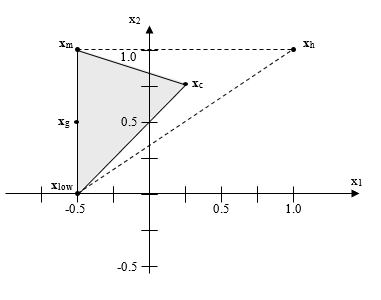

- **Second iteration** – We need to re-order the new points:

                   
$$f(x_{low}) = 0.25,   f(x_m) = 1.75,   f(x_c) = 1.375$$


-  Hence $x_m$ is now the worst point, while $x_1$ is still the best point. Hence:

$x_h = x_m=$${\left[\begin{array}{c}
-0.5\\
1
\end{array}\right]}$, $x_m=x_c=$${\left[\begin{array}{c}
0.25\\
0.75
\end{array}\right]}$ and $x_{low}=$${\left[\begin{array}{c}
-0.5\\
0
\end{array}\right]}$

- The new centroid $x_g$ is:

$x_g=0.5(x_{low}+x_m)=0.5$${\left[\begin{array}{c}
-0.25\\
0.75
\end{array}\right]}$=${\left[\begin{array}{c}
-0.125\\
0.375
\end{array}\right]}$

- We now carry out reflection of $x_h$ about $x_g$ to obtain a new point $x_r$:


$$x_r  = 2x_g– x_h=$$

$$2{\left[\begin{array}{c}
-0.125\\
0.375
\end{array}\right]}-{\left[\begin{array}{c}
-0.5\\
1
\end{array}\right]}={\left[\begin{array}{c}
0.25\\
-0.25
\end{array}\right]}$$


- The function output at this point is $f(x_r) = 0.125$. 

- Since  $f(x_r) < f(x_{low})$, we need to consider expansion by looking at a point beyond $x_r$. This new point $x_e$ is determined as follows:


$$x_e = x_g (1 - \mu) + \mu x_r$$


- Taking $\mu = 2$ gives:


$$x_e =$$

$${\left[\begin{array}{c}
-0.125\\
0.375
\end{array}\right]}\left(-1\right)+2{\left[\begin{array}{c}
0.25\\
-0.25
\end{array}\right]}={\left[\begin{array}{c}
0.625\\
-0.875
\end{array}\right]}$$


- The function output at this point is $f(x_e) = 1.375$. 

- This is clearly worse than $f(x_r)$, i.e. expansion does not improve the situation in this case! Hence, we replace $x_h$ with $x_r$ and the second iteration is complete.

- Our new simplex now looks like:

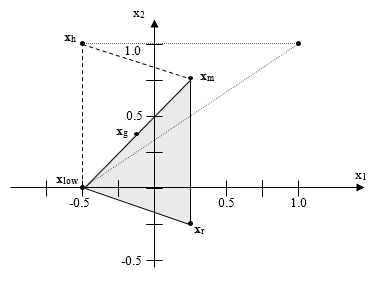

- **Matlab code part 01**

% Define the function
f = @(x) x(1)^2 + 2*x(2)^2;

% Initial starting points
x0 = [1; 1];
x1 = [-0.5; 1];
x2 = [-0.5; 0];

points = [x0, x1, x2];

% Evaluate function values at the starting points
f_values = [f(x0), f(x1), f(x2)];

[xh, xm, xlow, idx_high, idx_mid, idx_low] = order_points(points, f_values);

% Calculate centroid using the best two points
xg = 0.5*(xm + xlow);

% Reflection of the worst point about centroid
alpha = 1; % Reflection coefficient
xr = xg + alpha*(xg - xh);
fr = f(xr);

% Check if contraction is needed
if fr > f(xh)
    % Contraction step
    eta = 0.5; % Given contraction coefficient
    xc = xg*(1 - eta) + eta*xh;
    fc = f(xc);

    % Check if the contracted point is better than the worst point
    if fc < f(xh)
        points(:, idx_high) = xc; % Replace the worst point with the contracted point
        f_values(idx_high) = fc;
        
        % Reorder the points
        [xh, xm, xlow, idx_high, idx_mid, idx_low] = order_points(points, f_values);
    end
end

% Display the new simplex vertices and their function values
fprintf('Points after first iteration: \n');

Points after first iteration: 


disp('xh:');

xh:


disp(xh);

   -0.5000
    1.0000



fprintf('f(xh): %f\n', f(xh));

f(xh): 2.250000


disp('xm:');

xm:


disp(xm);

    0.2500
    0.7500



fprintf('f(xm): %f\n', f(xm));

f(xm): 1.187500


disp('xlow:');

xlow:


disp(xlow);

   -0.5000
         0



fprintf('f(xlow): %f\n', f(xlow));

f(xlow): 0.250000


- We were only asked for two iterations. Had we continued on, our simplex would eventually converge on the actual local minimum, which is given by $x^* = [0\quad 0]^T$.

- The following Matlab graph shows 12 iterations of the Simplex method. We can clearly see that it is indeed converging towards the local minimum

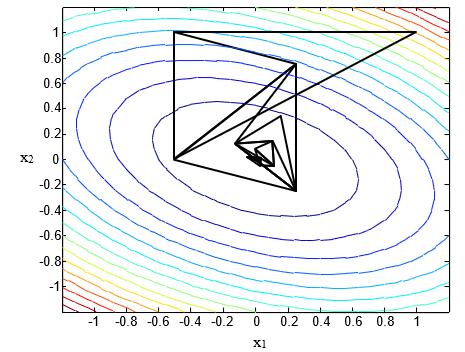

- All the direct methods (Univariate, DSC and Simplex) follow a similar pattern – the minimum is found by a sequence of line searches.

- The main disadvantage of these methods is that they can require numerous function evaluations in order to converge to the minimum point. As noted previously, the fewer function evaluations required the better the algorithm! 

- The key advantage of direct methods is that the determination of the search directions is independent of the local properties of the actual function. In particular they do not rely on the derivative of the function. As such, these methods are ideally suited for optimising noisy functions.

% Function to determine order of the points

function [xh, xm, xlow, idx_high, idx_mid, idx_low] = order_points(points, f_values)
    [sorted_values, indices] = sort(f_values, 'descend');
    xh = points(:, indices(1));
    xm = points(:, indices(2));
    xlow = points(:, indices(3));
    idx_high = indices(1);
    idx_mid = indices(2);
    idx_low = indices(3);
end
